% 参数设置
c = physconst("LightSpeed");
frequency = 7.9872e9;
lambda = c / frequency;
antennaSpacing = lambda * 0.5;
phase_offset = 0.17; 





% 初始化存储所有文件结果的变量
all_main_pdoa = [];
all_main_degree = [];

all_secondary_pdoa = [];
all_secondary_degree = [];

% 文件列表（假设有10个文件）




file_names = {};







for file_num = 1:3
    file_names{end+1} = sprintf('.\\Data\\data_for_doubleAOA_new\\0\\processed_rtt_files\\processed_test0_ping%d.txt', file_num);











end


% 循环处理每个文件
for file_idx = 1:length(file_names)
    filename = file_names{file_idx};
    fprintf('正在处理文件: %s\n', filename);
    
    % 检查文件是否存在
    if ~exist(filename, 'file')
        fprintf('文件不存在: %s\n', filename);
        continue;
    end
    
    fid = fopen(filename, 'r');
    rawData = textscan(fid, '%s', 'Delimiter', '\n');
    fclose(fid);
    
    lines = rawData{1};
    
    % 初始化存储变量
    sn_len = [];
    Ipatov_CIR = [];
    STS0_CIR = [];
    STS1_CIR = [];
    
    % 状态标志
    current_mode = '';
    inside_CIR_block = false;
    
    % 解析文件内容
    for i = 1:length(lines)
        line = strtrim(lines{i});
        
        if contains(line, 'Sequence Number')
            tokens = regexp(line, 'Sequence Number[:\s]+(\d+)', 'tokens');
            if ~isempty(tokens)
                sn_len = [sn_len, str2double(tokens{1}{1})];
            end
        end
        
        % 检测 CIR 类型标志
        if contains(line, 'Printing Ipatov CIR')
            current_mode = 'Ipatov';
            inside_CIR_block = false;
        elseif contains(line, 'Printing STS0 CIR')
            current_mode = 'STS0';
            inside_CIR_block = false;
        elseif contains(line, 'Printing STS1 CIR')
            current_mode = 'STS1';
            inside_CIR_block = false;
        end
        
        % 检测数据块边界
        if contains(line, '_________________________________')
            inside_CIR_block = ~inside_CIR_block;
            continue;
        end
        
        % 提取CIR数据
        if inside_CIR_block
            data_tokens = regexp(line, '(-?\d+),(-?\d+)', 'tokens');
            if ~isempty(data_tokens)
                I_val = str2double(data_tokens{1}{1});
                Q_val = str2double(data_tokens{1}{2});
                complex_val = I_val + 1j * Q_val;
                
                if strcmp(current_mode, 'Ipatov')
                    Ipatov_CIR(end+1, 1) = complex_val;
                elseif strcmp(current_mode, 'STS0')
                    STS0_CIR(end+1, 1) = complex_val;
                elseif strcmp(current_mode, 'STS1')
                    STS1_CIR(end+1, 1) = complex_val;
                end
            end
        end
    end
    
    % 重新组织CIR数据
    if length(STS0_CIR) >= 512 && length(STS1_CIR) >= 512
        packets_num = floor(length(STS0_CIR)/512);
        STS0_CIR = reshape(STS0_CIR(1:512 * packets_num), 512, packets_num).';
        STS1_CIR = reshape(STS1_CIR(1:512 * packets_num), 512, packets_num).';
        
        % 如果包数为奇数，丢弃最后一行
        if mod(packets_num, 2) ~= 0
            STS0_CIR(end, :) = [];
            STS1_CIR(end, :) = [];
            packets_num = packets_num - 1;
        end
        
        % 初始化当前文件的AOA变量
        aoa_pdoa_values_main = [];
        aoa_degree_values_main = [];
        aoa_pdoa_values_secondary = [];
        aoa_degree_values_secondary = [];
        
        % 处理每个数据包
        for i = 1:packets_num
            STS0_data = STS0_CIR(i,:);  
            STS1_data = STS1_CIR(i,:);
            
            STS0_magnitude = abs(STS0_data);
            STS1_magnitude = abs(STS1_data);
            
            threshold = 0.1;
            min_peak_distance = 4;
            
            % 找峰值
            [peaks_STS0, locs_STS0] = findpeaks(STS0_magnitude, 'MinPeakHeight', threshold * max(STS0_magnitude), 'MinPeakDistance', min_peak_distance);
            [peaks_STS1, locs_STS1] = findpeaks(STS1_magnitude, 'MinPeakHeight', threshold * max(STS1_magnitude), 'MinPeakDistance', min_peak_distance);
            
            % 检查是否找到足够的峰值
            if length(locs_STS0) < 2 || length(locs_STS1) < 2
                continue;
            end
            
            % 主峰和次强峰索引
            peak_index1_STS0 = locs_STS0(1);
            peak_index2_STS0 = locs_STS0(2);
            peak_index1_STS1 = locs_STS1(1);
            peak_index2_STS1 = locs_STS1(2);
            
            % 主峰相位差计算
            STS0_phase_main = angle(STS0_data(peak_index1_STS1));
            STS1_phase_main = angle(STS1_data(peak_index1_STS1));
            phase_difference_main = STS1_phase_main - STS0_phase_main - phase_offset;
            phase_difference_main = mod(phase_difference_main + pi, 2*pi) - pi;
            
            theta_radians_main = asin(phase_difference_main * c / (2 * pi * antennaSpacing * frequency));
            theta_degrees_main = rad2deg(theta_radians_main);
            
            aoa_pdoa_values_main(end+1) = phase_difference_main;
            aoa_degree_values_main(end+1) = theta_degrees_main;
            
            % 次强峰相位差计算
            STS0_phase_secondary = angle(STS0_data(peak_index2_STS1));
            STS1_phase_secondary = angle(STS1_data(peak_index2_STS1));
            phase_difference_secondary = STS1_phase_secondary - STS0_phase_secondary - phase_offset;
            phase_difference_secondary = mod(phase_difference_secondary + pi, 2*pi) - pi;
            
            theta_radians_secondary = asin(phase_difference_secondary * c / (2 * pi * antennaSpacing * frequency));
            theta_degrees_secondary = rad2deg(theta_radians_secondary);
            
            aoa_pdoa_values_secondary(end+1) = phase_difference_secondary;
            aoa_degree_values_secondary(end+1) = theta_degrees_secondary;
        end
        
        % 存储当前文件的结果
        if ~isempty(aoa_pdoa_values_main)
            all_main_pdoa = [all_main_pdoa; aoa_pdoa_values_main(:)];
            all_main_degree = [all_main_degree; aoa_degree_values_main(:)];
            all_secondary_pdoa = [all_secondary_pdoa; aoa_pdoa_values_secondary(:)];
            all_secondary_degree = [all_secondary_degree; aoa_degree_values_secondary(:)];
            
            % 显示当前文件统计结果
            fprintf('文件 %d 统计:\n', file_idx);
            fprintf('  主峰 - PDOA均值: %.4f, 标准差: %.4f\n', mean(aoa_pdoa_values_main), std(aoa_pdoa_values_main));
            fprintf('  主峰 - 角度均值: %.2f°, 标准差: %.2f°\n', mean(aoa_degree_values_main), std(aoa_degree_values_main));
            fprintf('  次峰 - PDOA均值: %.4f, 标准差: %.4f\n', mean(aoa_pdoa_values_secondary), std(aoa_pdoa_values_secondary));
            fprintf('  次峰 - 角度均值: %.2f°, 标准差: %.2f°\n', mean(aoa_degree_values_secondary), std(aoa_degree_values_secondary));
            fprintf('  数据点数: %d\n\n', length(aoa_pdoa_values_main));
        end
    else
        fprintf('文件 %d 数据不足，跳过处理\n\n', file_idx);
    end
end

正在处理文件: .\Data\data_for_doubleAOA_new\0\processed_rtt_files\processed_test0_ping1.txt


文件 1 统计:


  主峰 - PDOA均值: 0.0462, 标准差: 0.6528


  主峰 - 角度均值: 0.88°, 标准差: 12.03°


  次峰 - PDOA均值: 0.2542, 标准差: 0.2737


  次峰 - 角度均值: 4.66°, 标准差: 5.02°


  数据点数: 76



正在处理文件: .\Data\data_for_doubleAOA_new\0\processed_rtt_files\processed_test0_ping2.txt


文件 2 统计:


  主峰 - PDOA均值: 0.1248, 标准差: 0.6688


  主峰 - 角度均值: 2.34°, 标准差: 12.33°


  次峰 - PDOA均值: 0.2063, 标准差: 0.2692


  次峰 - 角度均值: 3.78°, 标准差: 4.93°


  数据点数: 72



正在处理文件: .\Data\data_for_doubleAOA_new\0\processed_rtt_files\processed_test0_ping3.txt


文件 3 统计:


  主峰 - PDOA均值: 0.1407, 标准差: 0.6444


  主峰 - 角度均值: 2.61°, 标准差: 11.89°


  次峰 - PDOA均值: 0.2167, 标准差: 0.3153


  次峰 - 角度均值: 3.97°, 标准差: 5.78°


  数据点数: 48




% 显示总体统计结果
fprintf('=== 所有文件总体统计结果 ===\n');

=== 所有文件总体统计结果 ===


主峰总体统计:


  PDOA均值: 0.0982, 标准差: 0.6547


  角度均值: 1.84°, 标准差: 12.07°


  总数据点数: 196



次强峰总体统计:


  PDOA均值: 0.2274, 标准差: 0.2822


  角度均值: 4.17°, 标准差: 5.17°


  总数据点数: 196



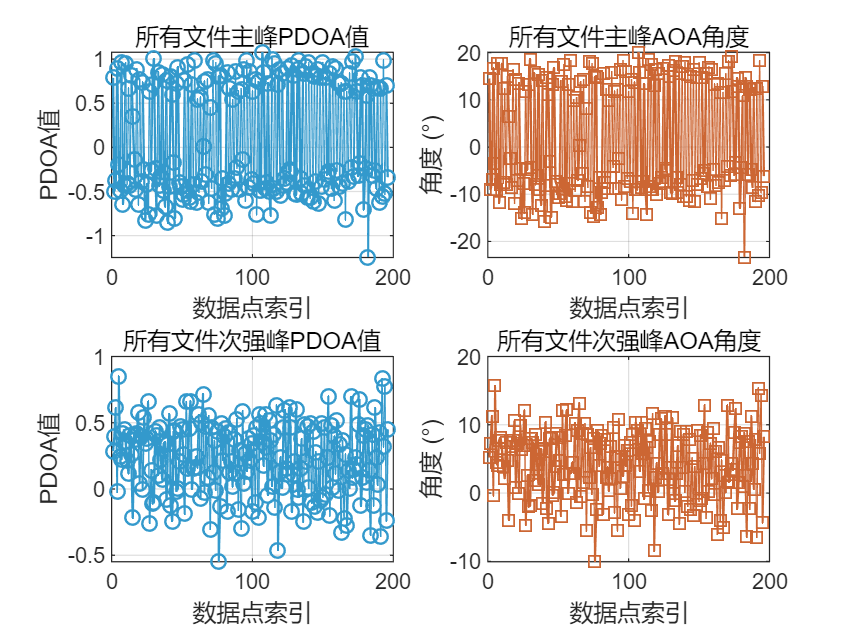

if ~isempty(all_main_pdoa)
    fprintf('主峰总体统计:\n');
    fprintf('  PDOA均值: %.4f, 标准差: %.4f\n', mean(all_main_pdoa), std(all_main_pdoa));
    fprintf('  角度均值: %.2f°, 标准差: %.2f°\n', mean(all_main_degree), std(all_main_degree));
    fprintf('  总数据点数: %d\n\n', length(all_main_pdoa));
    
    fprintf('次强峰总体统计:\n');
    fprintf('  PDOA均值: %.4f, 标准差: %.4f\n', mean(all_secondary_pdoa), std(all_secondary_pdoa));
    fprintf('  角度均值: %.2f°, 标准差: %.2f°\n', mean(all_secondary_degree), std(all_secondary_degree));
    fprintf('  总数据点数: %d\n\n', length(all_secondary_pdoa));
    
    % 绘制总体结果图
    figure;
    subplot(2,2,1);
    plot(all_main_pdoa, '-o', 'LineWidth', 1, 'Color', [0.2 0.6 0.8]);
    title('所有文件主峰PDOA值');
    xlabel('数据点索引');
    ylabel('PDOA值');
    grid on;
    
    subplot(2,2,2);
    plot(all_main_degree, '-s', 'LineWidth', 1, 'Color', [0.8 0.4 0.2]);
    title('所有文件主峰AOA角度');
    xlabel('数据点索引');
    ylabel('角度 (°)');
    grid on;
    
    subplot(2,2,3);
    plot(all_secondary_pdoa, '-o', 'LineWidth', 1, 'Color', [0.2 0.6 0.8]);
    title('所有文件次强峰PDOA值');
    xlabel('数据点索引');
    ylabel('PDOA值');
    grid on;
    
    subplot(2,2,4);
    plot(all_secondary_degree, '-s', 'LineWidth', 1, 'Color', [0.8 0.4 0.2]);
    title('所有文件次强峰AOA角度');
    xlabel('数据点索引');
    ylabel('角度 (°)');
    grid on;
else
    fprintf('没有有效数据可统计\n');
end